# Pattern separation tutorial

This is a tutorial on the **pattern separation toolbox**. The techniques and measures in the toolbox are fully described in the paper 'Robust and consistent measures of pattern separation based on information theory and demonstrated in the dentate gyrus' (Bird, Cuntz, & Jedlicka, 2022). 

The toolbox is built around a main function 'analyse_pattern_separation', which takes cell arrays of spike times or voltage traces as arguments and computes a variety of classical and information theoretic pattern separation measures. To get started with the toolbox, please follow the first section '**First steps and basic usage**'. This section generates synthetic ensembles of spike times and analyses them using the default settings. The following sections cover some of the more advanced and customisable functionality of the toolbox:

- **Changing options in the main analysis function. **This section covers basic changes to compute transfer entropy, use the Kozachenko-Leonenko estimators for informational quantities, or disable parallelisation within the analysis function.

- **Analysing voltage vectors. **This section covers how to analyse sets of voltage vectors and convert them to sets of spike times for further analysis.

- **Pattern separation in expansion systems. **This section deals with situations where the number of output units is larger than the number of input spike trains and there is no way to assign each output to a single input. In this case, the space of spike codes that can be applied is reduced.

- **Mutual information. **This section goes into more detail on the options around the mutual information calculations.

- **Redundancy reduction. **This section goes into more detail on the options around the redundancy calculations.

- **Transfer entropy. **This section goes into more detail on the options around the transfer entropy calculations.

- **Classical measures. **This sections shows how to use the toolbox to compute 'classical' pattern separtion measures without an information theoretic component.

## First steps and basic usage

### Add subfolders to Matlab path

cd .. % Go back to the 'Pattern_separation_toolbox' main folder
start_pattern_separation % Check dependencies are installed and add necessary subfolders to the path

### Generate synthetic data to demonstrate the main functions

input_spiketimes = phase_locked(16,5,8,0.7,6); % Generate a phase-locked spike ensemble, with 5 component trains, a spiking rate of 8Hz, a correlation strength of 0.7, and a phase rate of 6Hz
output_spiketimes = spike_thinner_random(input_spiketimes,8,0.5); % Generate a set of 8 output ensembles by (uniformly) randomly removing half of the input spikes

### Analyse pattern separation and view major ouputs

patsep = analyse_pattern_separation(input_spiketimes,output_spiketimes); % Run full pattern separation analysis with default settings
[patsep.info.spMI , patsep.info.RRR] % Print key information theoretic measures (sparsity-weighted mutual information and relative redundancy reduction)

ans =     2.2468   13.9561


[patsep.classical.orthogonalisation , patsep.classical.decorrelation , patsep.classical.wass_dist] % Print some classical pattern separation measures for comparison (orthogonalisation, decorrelation, and Wasserstein distance)

ans =     0.0488    0.0126    0.2698


### View details of mutual information, redundancy, and sparsity

patsep.info_details.MI % Raw mutual information

ans = 4.4461

patsep.info_details.best_binsize % Optimal binsize for mutual information calculation (ms)

ans = 782.4375

patsep.info_details.input_code % Optimal spike code for input ensemble

ans = 'rate_local'

patsep.info_details.output_code % Optimal spike code for output ensemble

ans = 'temporal'


patsep.info_details.RR % Raw redundancy reduction

ans = 3.1390

patsep.info_details.input_redundancy % Redundancy of input ensemble

ans = 3.1751

patsep.info_details.output_redundancy % Redundancy of output ensemble

ans = 0.0362

patsep.info_details.redundancy_binsize % Optimal binsize for redundancy calculation (ms)

ans = 978

patsep.info_details.input_redundancy_code % Optimal spike code for input ensemble redundancy

ans = 'rate_ensemble'

patsep.info_details.output_redundancy_code % Optimal spike code for input ensemble redundancy

ans = 'spatial'


patsep.sparsity.n_spike_in % Number of spikes in input ensemble

ans = 631

patsep.sparsity.n_spike_out % Total number of spikes across all repetitions of the output ensemble

ans = 2497

patsep.sparsity.sparsity % Sparsity ratio

ans = 0.5053

### Plot rasters of the input and (first) output ensembles

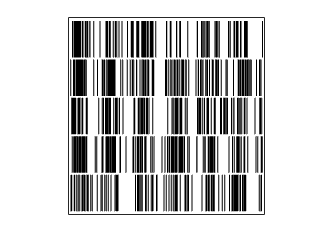

plot_raster(input_spiketimes)

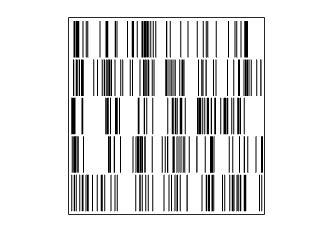

plot_raster(output_spiketimes(:,1))

## Changing options in the main analysis function

### Compute transfer entropy instead of mutual information

patsep = analyse_pattern_separation(input_spiketimes,output_spiketimes,'transfer_entropy',true);
patsep.info.spTE % Print sparsity-weighted transfer entropy

ans = 1.3150

### Estimate mutual information and redundancy instead of trying an explicit calculation

patsep = analyse_pattern_separation(input_spiketimes,output_spiketimes,'estimate',true);
patsep.info_details.MI % Print estimated raw mutual information using the Kozachenko-Leonenko method

ans = 3.2495

patsep.info_details.MI_bounds % Print 95% confidence interval around estimated MI

ans =     3.0462    3.4529


### Change bin size for classical measures to 100ms

patsep = analyse_pattern_separation(input_spiketimes,output_spiketimes,'classical_binsize',100);
[patsep.classical.orthogonalisation , patsep.classical.decorrelation] % Print classical measures with a binsize of 100ms

ans =     0.1941    0.0550


### Disable parallel computation

Sometimes it may be impractical to parallelise the calculations within the 'analyse_pattern_separation' function (or the parallel computing Matlab toolbox is unavailable). In this case, the keyword 'parallel' should be set to false.

patsep = analyse_pattern_separation(input_spiketimes,output_spiketimes,'parallel',false);

## Analysing voltage vectors

The 'analyse_pattern_separation' function can also compute pattern separation metrics on raw voltage traces. To demonstrate this, we can load in sample modelled voltage outputs and run the main function on the ensemble of voltage vectors.

load('example_data/example_voltages.mat') % Load example voltage traces to the workspace
patsep = analyse_pattern_separation(input_spikes,voltage_traces); % Automatically convert voltages to spike times and analyse

It may also be useful to simply convert the ensemble of voltage vectors to an ensemble of spike times for further analysis:

output_spiketimes=cell(size(voltage_traces,1),size(voltage_traces,2));
for train_ind=1:size(voltage_traces,1)
    for rep_ind=1:size(voltage_traces,2)
        output_spiketimes{train_ind,rep_ind}=voltage2times(voltage_traces{train_ind,rep_ind});
    end
end

## **Pattern separation in expansion systems**

### Generate synthetic data for an expansion system and run the main function

Sometimes it is not clear which inputs map to which outputs, such as in the mushroom body. In this case, it is still possible to use information theoretic measures of pattern separation.

output_spiketimes_expand = spike_expansion_random(input_spiketimes); % Expand each input trace to between one and five output traces while removing spikes
patsep = analyse_pattern_separation(input_spiketimes,output_spiketimes_expand); % This will typically generate a warning that local spike codes cannot be used as the number of output trains differs from the number of input trains

### View results

patsep.info.spMI % Sparsity-weighted mutual information

ans = 2.1269

patsep.info_details.input_code % Optimal spike code for input ensemble (cannot be a local code)

ans = 'rate_ensemble'

patsep.info_details.output_code % Optimal spike code for output ensemble (cannot be a local code)

ans = 'spatial'

## Mutual information

If you only require the mutual information between the input and the output, the following code can be used:

num_params=struct; % Set up an empty structure to contain numerical parameters
num_params.wordsize=5; % Specify an appropriate word size for the temporal codes (see the paper)
MIoptions='-max_bins -max_code -par'; % Set up options to maximise the information over different bin sizes and different spiking codes using parallelisation
MI_obj=MI_function(input_spiketimes,output_spiketimes,[],num_params,MIoptions) % Compute the mutual information

MI_obj = struct with fields:
       all_codes: {4×4 cell}
    all_binsizes: [4×4 double]
         all_MIs: [4×4 double]
       best_code: {'rate_local'  'rate_local'}
    best_binsize: 782.5000
              MI: 4.1927


[MI_obj.MI , MI_obj.best_code] % Display the mutual information and spiking codes that maximise this quantity for the input and output ensembles

ans = 1×3 cell array
    {[4.1927]}    {'rate_local'}    {'rate_local'}


The sparsity is then simply:

sparsity_obj=calculate_sparsity(input_spiketimes,output_spiketimes);
sparsity_obj.sparsity % Display sparsity

ans = 0.9719

If you believe that a specific spiking code is most appropriate for your data, this can be specified:

MIoptions='-max_bins -par'; % Adjust options to use a single code
MI_obj=MI_function(input_spiketimes,output_spiketimes,'spatial',num_params,MIoptions) % Specify that a spatial code should be used for both the input and output ensembles

MI_obj = struct with fields:
       best_code: {'spatial'  'spatial'}
    best_binsize: 274.5000
              MI: 0.3732


It is also possible to specify different spiking codes for the input and output ensembles as a pair '{input_code,output_code}':

MI_obj=MI_function(input_spiketimes,output_spiketimes,{'spatial','temporal'},num_params,MIoptions)

MI_obj = struct with fields:
       best_code: {'spatial'  'temporal'}
    best_binsize: 288.7812
              MI: 0.0714


Finally, if you need to fix the binsize (usually for validating your results against other analyses), it is possible to alter the 'num_params' structure and remove the '-max_bins' option:

num_params.binsize=100; % Binsize (in ms)
MIoptions='-par'; 
MI_obj=MI_function(input_spiketimes,output_spiketimes,[],num_params,MIoptions)

MI_obj = struct with fields:
       best_code: {'spatial'  'spatial'}
    best_binsize: 100
              MI: 0.1884


### Estimating mutual information

A different function is used to apply the Kozachenko-Leonenko estimation:

estMI_obj = estimate_MI(input_spiketimes,output_spiketimes,'-par'); % Estimate mutual information using parallelisation
MI=estMI_obj.MI % Display estimated mutual information 

MI = 6.5234

MI_bounds=estMI_obj.MI_bounds % Display 95% confidence interval

MI_bounds =     6.3103    6.7366


## **Redundancy reduction**

If you only require the redundancies of the inputs and outputs, the following code can be used:

num_params=struct; % Set up an empty structure to contain numerical parameters
num_params.wordsize=5; % Specify an appropriate word size for the temporal codes (see the paper)
RRoptions='-max_bins -max_code -par'; % Set up options to maximise the information over different bin sizes and different spiking codes using parallelisation
RR_obj=RR_function(input_spiketimes,output_spiketimes,[],num_params,RRoptions) % Compute the redundancies

RR_obj = struct with fields:
    all_binsizes: [4×4 double]
       best_code: {'rate_ensemble'  'rate_local'}
    best_binsize: 978.5000
              RR: 3.1751
            RRin: 3.1751
           RRout: 1.2289e-06
        RRbycode: [4×4 double]


[RR_obj.RRin RR_obj.RRout] % Display the input and output redundancies

ans =     3.1751    0.0000


Other options are identical to the mutual information options demonstrated above.

## **Transfer entropy**

The transfer entropy code is similar to that for the mutual information:

num_params=struct; % Set up an empty structure to contain numerical parameters
num_params.wordsize=5; % Specify an appropriate word size for the temporal codes (see the paper)
TEoptions='-max_bins -max_code -par'; % Set up options to maximise the information over different bin sizes and different spiking codes using parallelisation
TE_obj=TE_function(input_spiketimes,output_spiketimes,[],num_params,TEoptions) % Compute the redundancies

TE_obj = struct with fields:
       all_codes: {4×4 cell}
    all_binsizes: [4×4 double]
      all_delays: [4×4 double]
         all_TEs: [4×4 double]
       best_code: {'rate_ensemble'  'spatial'}
    best_binsize: 914
      best_delay: 610
              TE: 1.2513


The transfer entropy has two major differences to the mutual information and redundancy code. The first is that there is an additional parameter to optimise over: the delay or lag. This can be fixed as a numerical parameter: 

num_params.delay=50; % Specify a fixed delay for the transfer entropy calculations
TE_obj=TE_function(input_spiketimes,output_spiketimes,[],num_params,TEoptions) % Compute the redundancies

TE_obj = struct with fields:
       all_codes: {4×4 cell}
    all_binsizes: [4×4 double]
      all_delays: [4×4 double]
         all_TEs: [4×4 double]
       best_code: {'rate_ensemble'  'spatial'}
    best_binsize: 914
      best_delay: 610
              TE: 1.2513


The second major difference is that the Kozachenko-Leonenko estimation techniques have not been implemented for transfer entropy.

## **Classical measures**

The **pattern separation toolbox **can also be used to compute 'classical' pattern separtion measures that do not have an information theoretic component. The first three functions can take a specified binsize by setting:

num_params=struct; % Set up an empty structure to contain numerical parameters
num_params.binsize=50; % Set the binsize for the orthogonalisation, decorrelation, and Hamming distance.

### Orthogonalisation

orth_obj = orthogonalisation(input_spiketimes,output_spiketimes);
[orth_obj.NDP_est , orth_obj.SF_est] % Display the orthogonalisation and scaling measures

ans =     0.1021    0.0410


### Decorrelation

[decorr_obj] = decorrelation(input_spiketimes,output_spiketimes);
decorr_obj.decorr_est % Display the decorrelation measure

ans = 0.0303

### Hamming distance

[hamming_obj] = hamming_sparsity(input_spiketimes,output_spiketimes);
hamming_obj.hamming_est % Display the Hamming distance measure

ans = 22.8882

### Wasserstein distance

[dist_obj] = distance(input_spiketimes,output_spiketimes);
dist_obj.dist_est % Display the Wasserstein distance measure

ans = 0.4236